##                                                                 Trabalho Avaliativo - Robótica

clear; clc;

### Prática 1

% Calculo da reta tangente ao ponto de inflexao
syms S t;

M = 1; % Amplitude do degrau unitário

% Define uma função de transferência simbólica
Gsyms = 1.2*(exp(-10*S))/((5*S + 1)*(2.5*S + 1));
Gt = ilaplace(Gsyms/S); % Calcula a transformada inversa de Laplace para obter a resposta no domínio do tempo
                        % Só da pra fazer Laplace inversa em funções simbólicas.

% Calcula a segunda derivada da função Gt em relação ao tempo t e simplifica a expressão.
d2Gt = simplify(diff(Gt,t,2));
pontos_de_inflexao = double(solve(d2Gt == 0,t))

pontos_de_inflexao =     9.0000
   13.4657


t_inflex = pontos_de_inflexao(2); % considera o 2° ponto

% Calcula o valor da função Gt no ponto de inflexão.
y_inflex = double(subs(Gt, t, t_inflex));
dGt = simplify(diff(Gt,t)); % Calcula a primeira derivada da função Gt.
m = double(subs(dGt,t,t_inflex)); % Calcula o valor da inclinação (derivada) da curva no ponto de inflexão.

% Define a equação da reta tangente ao ponto de inflexão. Yo yo = mu xo xo
tanInfSyms = m*t - m*t_inflex + y_inflex;
T = double(solve(tanInfSyms==0,t));
t = (0:0.1:45); % 45 por conta do limite do grafico
tanInflex = m*t - m*t_inflex + y_inflex; % Calcula o ponto onde a reta tangente cruza o eixo horizontal.

% Define a função de transferência G(s) do sistema.
s = tf('s');
G = 1.2*(exp(-10*s))/((5*s + 1)*(2.5*s + 1))

G =
 
                       1.2
  exp(-10*s) * --------------------
               12.5 s^2 + 7.5 s + 1
 
Continuous-time transfer function.



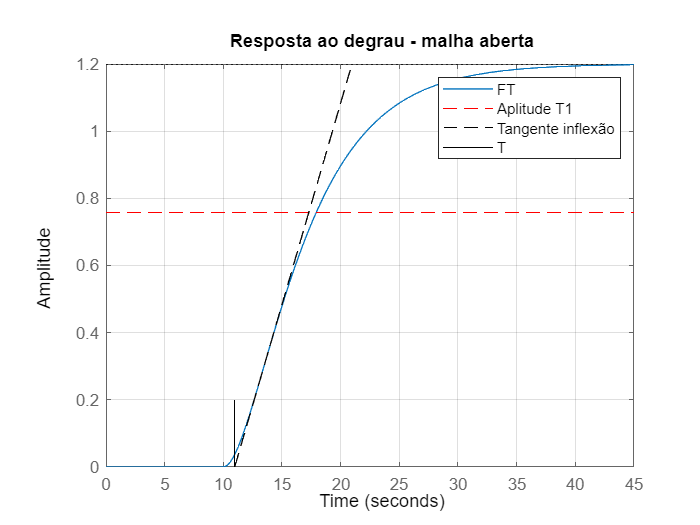

% step(feedback(G,1))
y = [dcgain(G)*0.632, dcgain(G)*0.632];
x = [0,45]; % 45 por conta do limite do grafico
step(G*M)
hold on
plot(x,y,'--r') % plotando a reta em 63,2% do valor final da reta
plot(t,tanInflex,'--k') % plotando a reta tangente
plot([T,T],[0,0.2],'k') % 0.2 valor arbitrario. Reta para obter o retardo de tempo de forma analítica
grid on
title("Resposta ao degrau - malha aberta")
legend("FT","Aplitude T1","Tangente inflexão","T")
hold off

% Aplicando o método de Ziegler-Nichols
syms t;
Mlinha = dcgain(G);
T;
T1 = double(solve(Gt==(dcgain(G)*0.632),t));
tau = T1 - T

tau = 6.9576

k = Mlinha/M

k = 1.2000

Gapx = (k*exp(-T*s))/(tau*s + 1)

Gapx =
 
                   1.2
  exp(-11*s) * -----------
               6.958 s + 1
 
Continuous-time transfer function.



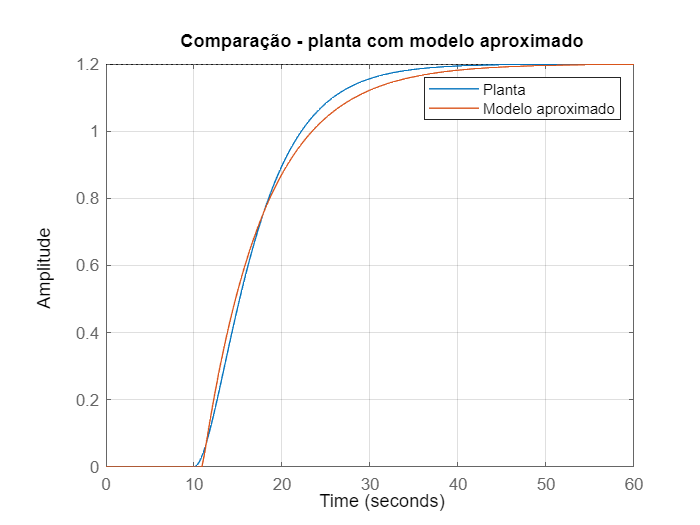

step(G*M)
hold on
step(Gapx*M)
grid on
title("Comparação - planta com modelo aproximado")
legend("Planta","Modelo aproximado")
hold off

Kp = 1.2*tau/T

Kp = 0.7614

Ti = 2*T;

Ti = 21.9315

Ki = 
Td = 0.5*T

Td = 5.4829

% Calculo das constantes 

% clear all
% close all
warning off
global kp ki kd erro tempo
options = optimset('Display','iter','TolFun',1e-8,'TolX',1e-8);
x0 = [Kp Ti Td];
% [x, fval, exitflag, output]= fminsearch(@objective_function_IAE,x0,options)
[x, fval, exitflag, output]= fminsearch(@objective_function_ITAE,x0,options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1      8.12999e+27         
     1            4      8.12999e+27         initial simplex
     2            6      2.09578e+27         expand
     3            7      2.09578e+27         reflect
     4            9      7.53615e+26         expand
     5           11       3.7939e+25         expand
     6           12       3.7939e+25         reflect
     7           14      6.84238e+22         expand
     8           16      1.35787e+12         expand
     9           17      1.35787e+12         reflect
    10           19      1.35787e+12         contract outside
    11           21      1.35787e+12         contract inside
    12           23      1.35787e+12         contract inside
    13           25      1.35787e+12         contract inside
    14           27      1.64542e+11         contract outside
    15           29      1.56643e+10         contract inside
    16           31      9.70708e+08         cont

x =     0.3405    0.0485    2.7879


fval = 1.7424e+04

exitflag = 1

output = struct with fields:
    iterations: 304
     funcCount: 541
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-08 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-08 ↵'


% [x, fval, exitflag, output]= fminsearch(@objective_function_MSE,x0,options)